%% Read in csv files and make vars
run1 = csvread('linear_tof_run1.csv', 1, 0);
run2 = csvread('linear_tof_run2.csv', 1, 0);

%Run1 data
run1_lin = run1(:, 1);
run1_tof = run1(22:end, 2);

%Run2 data
run2_lin = run2(:, 1);
run2_tof = run2(:, 2);

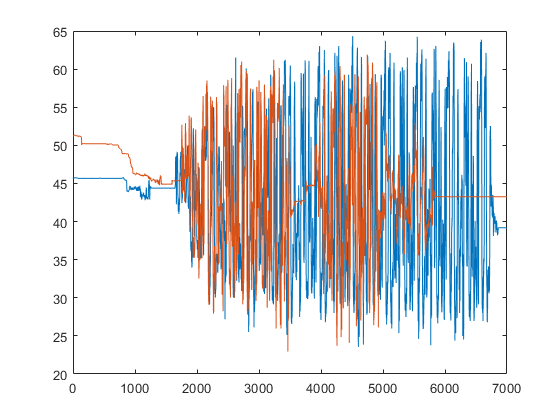

%% Linear potentiometer data analysis
%coefficients determined from original calibration data in excel
lin_grad = 0.0755;
lin_int = 1.6561;

run1_ext = lin_grad.*run1_lin + lin_int;
run2_ext = lin_grad.*run2_lin + lin_int;

figure
plot(run1_ext)
hold on
plot(run2_ext)
axis([0 7000 20 65])

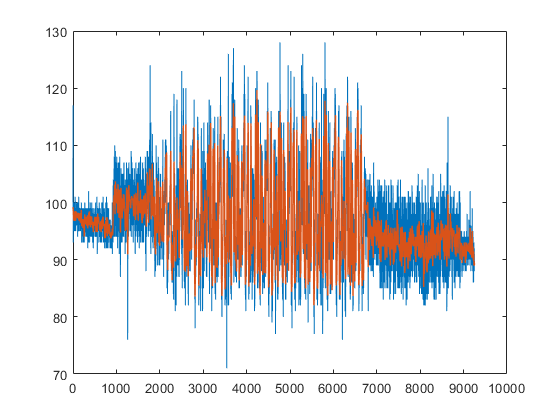

%% ToF data analysis
d = designfilt('lowpassiir','FilterOrder',15, ...
    'HalfPowerFrequency',0.15,'DesignMethod','butter');
y1_filt = filtfilt(d,run1_tof);

figure
plot(run1_tof)
hold on
plot(y1_filt, 'Linewidth', 1)
axis([0 10000 70 130])